clear; clc; clf

%% Shape Estimation EM Sensor Plot for Bent Shape
% Reading data from .csv file
data = readmatrix('Bent20points.csv');                  % Data is in meters
x_coords = data(:,1);                        % Defining x,y,z coordinates from data
y_coords = data(:,2);
angles = (data(:,3));

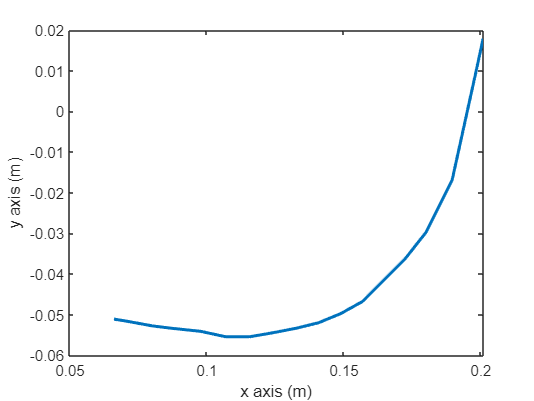

configs = [x_coords'; y_coords'; angles'];
X = configs(1,:,:);
Y = configs(2,:,:);
Angles = configs(3,:,:);

plot(X,Y, 'LineWidth', 2)
xlabel("x axis (m)")
ylabel("y axis (m)")

% title("True Snake Configuration")
% axis equal

hold on
best_sens = best_sensor_placement(X, Y, false)

best_sens =     0.1328   -0.0534    9.0000


estimatedCoords = Hermite(X, Y, Angles, best_sensor_placement(X, Y, false), true)

estimatedCoords =     0.0662    0.0664    0.0666    0.0668    0.0670    0.0672    0.0674    0.0676    0.0678    0.0680    0.0682    0.0684    0.0686    0.0688    0.0690    0.0692    0.0694    0.0696    0.0698    0.0700    0.0702    0.0704    0.0706    0.0708    0.0710    0.0712    0.0714    0.0716    0.0718    0.0720    0.0722    0.0724    0.0726    0.0728    0.0730    0.0732    0.0734    0.0736    0.0738    0.0740    0.0742    0.0744    0.0746    0.0748    0.0750    0.0752    0.0754    0.0756    0.0758    0.0760
   -0.0511   -0.0511   -0.0512   -0.0512   -0.0512   -0.0512   -0.0513   -0.0513   -0.0513   -0.0513   -0.0514   -0.0514   -0.0514   -0.0514   -0.0515   -0.0515   -0.0515   -0.0515   -0.0516   -0.0516   -0.0516   -0.0516   -0.0517   -0.0517   -0.0517   -0.0518   -0.0518   -0.0518   -0.0518   -0.0519   -0.0519   -0.0519   -0.0520   -0.0520   -0.0520   -0.0520   -0.0521   -0.0521   -0.0521   -0.0522   -0.0522   -0.0522   -0.0522   -0.0523   -0.0523   -0.0523   -0.0524   -0.0524 

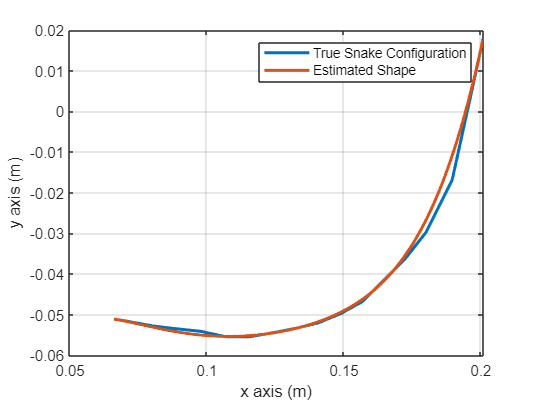

% Y_est =  estimatedCoords(2,:);
% X_est =  estimatedCoords(1,:);
% scatter(best_sens(1,1),best_sens(1,2), 'LineWidth', 2)
legend('True Snake Configuration', 'Estimated Shape')
grid on
hold off

% sensorcoord = [];
% m_error = [];
% for i = 1:30
%     sensorcoord = [sensorcoord; [X(:,i) Y(:,i)]];  
% end
% for j = 2:29
%     estimatedCoords = Hermite(X, Y, Angles, [sensorcoord(j,:) j], true);
%     temp = MaxError(X, Y, Angles, estimatedCoords(2,:), estimatedCoords(1,:), true, true);
%     m_error = [m_error, temp(1)];
% end
hold off

Y_true = Y;
Y_estimate = [-0.0511224610000000, -0.0518189943017656, -0.0534776063769211, -0.0546432510088159, -0.0560537986579645, -0.0564959681555417, -0.0562631152938491, -0.0554083947300276, -0.0539537115685864, -0.0519804739586476, -0.0493910177045060, -0.0459119812893458, -0.0349019837269299, -0.0335139066192851, -0.0265218977158030, -0.0108349875959786, 0.0114215692230825, 0.0174605093588491 ];
estError = Y-Y_estimate;

ans = -0.0060

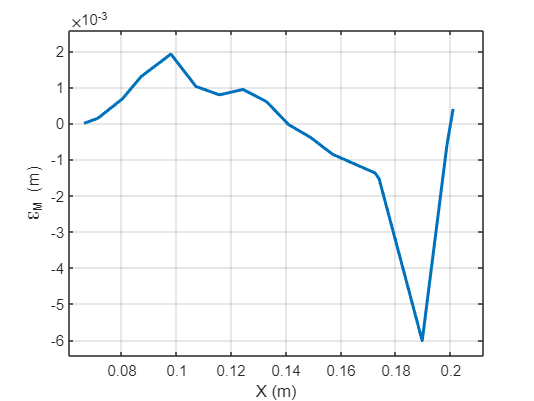

min(estError)
plot(X,estError, 'LineWidth', 2)
ylabel('ℇ_M (m)');
xlabel('X (m)');

grid on

Confignum = 2:1:29;
plot(Confignum, m_error)

% % %error plot
% m_error = [];
% for a = 1:1:length(X)
%     Est = Hermite(X, Y, Angles, [X(a), Y(a), a], false);
%     temp = MaxError(X, Y, Angles, Est(2,:), Est(1,:), true, true);
%     m_error = [m_error, temp(1)];
% end
% 
% plot(X, m_error, 'LineWidth', 2)
% grid on
% xlabel("X coordinates")
% ylabel("Error (m)")
% hold off

function area = EllipseArea(X, Y, s, drawEllipse)
    % X = all known x coordinates along the snake (array)
    % Y = all known y coordinates corresponding to X (array)
    % s = the link number at which the middle sensor is placed
    % drawEllipse = boolean. If true, function plots where the bounds are on the snake. if false, no plot
    
    num_links = length(X);
    si = [1,s,num_links];
    
    function distance = Distance(si_start, si_end)
        distance = sqrt((X(si_start)-X(si_end))^2+(Y(si_start)-Y(si_end))^2);
    end
    
    function length = Length(si_start, si_end)
        length = si_end - si_start;
    end
    
    function area_ell = Area(si_start, si_end)
        l = Length(si_start, si_end);
        d = Distance(si_start, si_end);
        a = l/2;
        b = sqrt((l/2)^2-(d/2)^2);
        area_ell = pi*a*b;
    end

    function draw_ellipse = draw_Ellipse(si_start, si_end)
        l = Length(si_start, si_end);
        d = Distance(si_start, si_end);
        a = l/2;
        b = sqrt((l/2)^2-(d/2)^2);
        
        x0 = ((X(si_start) + X(sx_end))/2); % x0,y0 ellipse centre coordinates
        y0 = ((Y(si_start) + Y(sx_end))/2);
        t=-pi:0.01:pi;
        x = x0 + a*cos(t);
        y = y0 + b*sin(t);
        
        ezplot(strcat('(((x-', string(x0),').^2)/(',string(a),'.^2))+(((y-',string(y0),').^2)/(', string(b),'.^2))=1'))
    end
    
    area = Area(si(1), si(2)) + Area(si(2), si(3));

    if drawEllipse
        figure(1)
        plot(X,Y)
        hold on
        draw_Ellipse(si(1), si(2))
        hold on
        draw_Ellipse(si(2), si(3))
        hold on
        xlabel("x axis (cm)")
        ylabel("y axis (cm)")
        title("True Snake Configuration")
        hold off
    end

end 
function bestPlacement = best_sensor_placement(X, Y, drawArea)
% X = all known x coordinates along the snake (array)
% Y = all known y coordinates corresponding to X (array)
% drawSnake = boolean. If true, function plots the snake configuration. if false, no plot
% drawArea = boolean. If true, function plots the area within the bound as sensor moves along links increases. if false, no plot
% bestPlacement = the X and Y of the best placement of  the sensor in space

    num_links = length(X);
          
    Area = []; 
    for i = 1:1:num_links
        temp = EllipseArea(X, Y, i, false);
        Area = [Area temp];    
    end
    
    [M,I] = min(Area);
    
    bestPlacement = [X(I), Y(I),I];
    
    if drawArea
        link_num = 1:1:num_links;
        plot(link_num, Area)
        xlabel("Link in which the sensor is placed")
        ylabel("Area swept by possible snake configurations")
    
    end
end

function estimatedCoords = Hermite(X, Y, Angles, Sensor, Plot)
    % credit to
    % https://drive.google.com/file/d/1042MCt0_oOZKdGjf7Ss3tw8KCNLl_z73/view
    % for majority of code

    % X = all known x coordinates along the snake (array)
    % Y = all known y coordinates corresponding to X (array)
    % Angles = angle of snake at every link (array)
    % Sensor = the X, Y, and angle of the position of the middle sensor
    % plot = boolean; if true, plot the estimated shape. Otherwise, do not plot
 
    num_links = length(X);
    n = 2; %for adding more sensors: input('Enter n for (n+1) nodes, n:  '); -> n = number of sensors (base is not a sensor)
    x = zeros(1,n+1);
    q = zeros(2*n+2,2*n+2);
    
    x = [X(1), Sensor(1), X((length(X)))];
    q(2*0+1,1) = Y(1);
    q(2*1+1,1) = Sensor(2);
    q(2*2+1,1) = Y(num_links);
    q(2*0+2,2) = tand(Angles(1));
    q(2*1+2,2) = tand(Angles((Sensor(3))));  
    q(2*2+2,2) = tand(Angles(num_links-1));
%     q(2*2+2,2) = tand(Angles((num_links)-1));
    %  for i = 0:n                   
    %    x(i+1) = input(' ');
    %    q(2*i+1,1) = input(' ');
    %    q(2*i+2,2) = input(' ');
    %  end            
    
    z = zeros(1,2*n+2);
    for i = 0:n
        z(2*i+1) = x(i+1);
        z(2*i+2) = x(i+1);
        q(2*i+2,1) = q(2*i+1,1);
        if i ~= 0 
            q(2*i+1,2) = (q(2*i+1,1)-q(2*i,1))/(z(2*i+1)-z(2*i));
        end
    end
    
    k = 2*n+1;
    for i = 2:k
        for j = 2:i
            q(i+1,j+1) = (q(i+1,j)-q(i,j))/(z(i+1)-z(i-j+1));
        end
    end
    
    %  fprintf('\nCoefficients of the Hermite polynomial are:\n ');
    %  for i = 0:k
    %     fprintf(' %11.8f \n', q(i+1,i+1));
    %  end
    
    %  fprintf('Now enter a point at which to evaluate the polynomial, x = \n');
    %  xx = input(' ');
    
    inter = [];
    for t = X(1):0.0002:X((length(X)))
        s = q(k+1,k+1)*(t-z(k));
        for i = 2:k
            j = k-i+1;
            s = (s+q(j+1,j+1))*(t-z(j));
        end
        s = s + q(1,1);
        inter = [inter s];
    end
    
    xpoints = X(1):0.0002:X((length(X)));
    
    estimatedCoords = [xpoints;inter];
    
    if Plot
        plot(xpoints,inter, 'LineWidth', 2)
    end
end

function errorAtPoint = ErrorAtPoint(x, X, Y, A, Y_est, X_est)
    % x = x coordinate of point at which you want to find the error at
    % X_est = all known x coordinates along the estimated snake (array)
    % Y_est = all known y coordinates along the estimated snake (array)
    % X = all known x coordinates along the snake (array)
    % Y = all known y coordinates corresponding to X (array)

    function distance = Distance(x1, x2, y1, y2)
        distance = sqrt((x1-x2)^2+(y1-y2)^2);
    end

    temp = X - x;
    for k = 1:1:length(X)
        if temp(k)<0 
            continue;
        else
            break;
        end
    end

    if k == length(X)
        y_real = Y(k);
    else
        y_real = Y(k)+tand(A(k));
    end
    
%     error estimation for closest point on est snake to real snake
    for h = X_est(1):0.0002:X_est(length(X_est))
       temp = X_est - h;
        for j = 1:1:length(X_est)
            if temp(j)<0
                continue;
            else
                break;
            end
        end
        
        if j == length(Y_est)
            y_est = Y_est(j);
        else
            hyp = Distance(X_est(j), X_est(j+1), Y_est(j), Y_est(j+1));
            op = Y_est(j)-Y_est(j+1);
            theta = asind(op/hyp);
            y_est = Y_est(j)+tand(theta)*(h-X_est(j));
        end
        
        dist = Distance(x, h, y_real, y_est);
        
        if h==X_est(1) || dist < minDist
            minDist = dist;
        end
    end
    errorAtPoint = minDist;
end

function [maxError,x, allError, minError, x_min] = MaxError(X, Y, A, Y_est, X_est, findAll, findMin)
    allErrorX = [];
    allErrorY = [];
    maxError = 0;
    minError = nan;
    x = 0;
    x2 = nan;
    for i = X(1):0.5:X(length(X))
        temp = ErrorAtPoint(i, X, Y, A, Y_est, X_est);
        if findAll
            allErrorX = [allErrorX, i];
            allErrorY = [allErrorY, temp];
        end
        if temp>maxError
            maxError = temp;
            x = i;
        end
        if findMin && (i == X(1) || temp<minError)
            minError = temp;
            x_min = i;
        end
    end
    allError = [allErrorX; allErrorY];
end






